# Symbolic Derivation of Projectile Dynamics using Eular-Lagrange Method

clear;clc;
addpath('../Eular-Lagrange/');

syms x y xd yd m c g real;

% Define Lagrangian = Kinetic Energy T - Potential Energy V
% https://sciencemeetsfiction.com/2020/07/04/why-does-the-lagrangian-equal-t-v/
T = 0.5*m*(xd^2+yd^2);
V = m*g*y;
L = T-V;

% Define Force F
v_mag = sqrt(xd^2+yd^2);
F = [-c*v_mag*xd -c*v_mag*yd];

% Define State Space q, qd and qdd
q = [x y];
qd = [xd yd];

## Eular-Lagrange

% d(dL/dqd)/dt - dL/dq = F
qdd = eular_lagrange2(L,q,qd,F)

$$qdd = \left(\begin{array}{c} -\frac{c\,\mathrm{xd}\,\sqrt{{\mathrm{xd}}^{2}+{\mathrm{yd}}^{2}}}{m}\\ -\frac{g\,m+c\,\mathrm{yd}\,\sqrt{{\mathrm{xd}}^{2}+{\mathrm{yd}}^{2}}}{m} \end{array}\right)$$

## Integrate

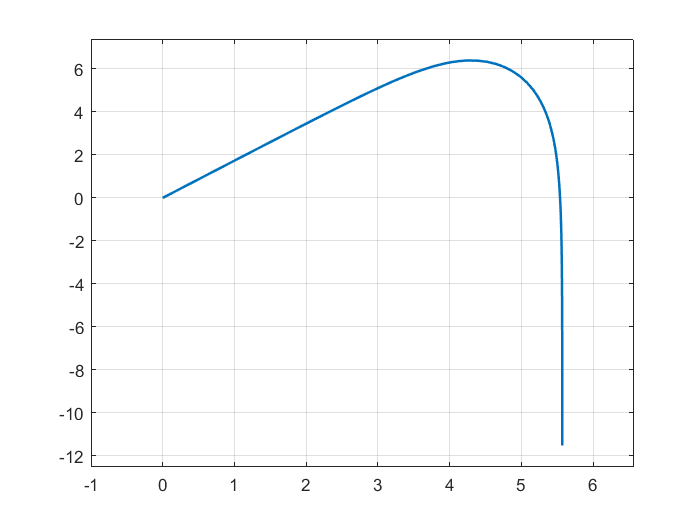

projectile_dynamics = @(t,s) [s(3); s(4); ...
    eval(subs(qdd(1),[m c g x y xd yd],[1 0.5 9.81 s(1) s(2) s(3) s(4)])); ...
    eval(subs(qdd(2),[m c g x y xd yd],[1 0.5 9.81 s(1) s(2) s(3) s(4)]))];

Tend = 5;
s0 = [0; 0; 100; 100*tan(pi/3)];
[t,s] = ode45(projectile_dynamics,[0 Tend],s0);

plot(s(:,1),s(:,2),'LineWidth',1.5);
axis([min(s(:,1))-1 max(s(:,1))+1 min(s(:,2))-1 max(s(:,2))+1]);
grid on;